% Problem 1
% 1.1
clear;
% create poly
poly = [816 -3835 6000 -3125];
% use root function to compute roots
x_root = roots(poly);

interval = [1.4 1.7];

figure(1);
ezplot(@(x) func(x), interval); grid;
xlabel('x in interval [1.4,1.7]');
ylabel('y value');

% use fzero to compute roots
init_guess = [1.45 1.55 1.65];% my initial guess

x_zero = zeros(1,3);
for i = 1:3
    x_zero(i) = fzero(@(x) func(x),init_guess(i));
    fprintf('%gth zeros of this poly using fzeros is %g\n',i, x_zero(i));
end

% 1.2
% newton's method

guess = linspace(1.4,1.7,10);
% generate some more guesses
% set the tolerance to stop
epsilon = 1e-10;

for i = 1:10
    iteration_time = 1;
    x_newton = guess(i);
    fprintf('initial guess is %g\n', x_newton);
    
    while abs(x_newton-Newton(x_newton))>epsilon
        x_newton = Newton(x_newton);
        iteration_time = iteration_time +1;
    end
    
    fprintf('after %g rounds of computation, the newton method converges at %g\n',iteration_time, x_newton);
end

% verify
x_v = 1.65;
lim = zeros(4,1);
c = abs(d2func(5/3)/(2*dfunc(5/3)));
fprintf(['verify with the initial guess 1.65, the relative error between \n' ...
    'limit of |e_k+1|/|e_k|^2 and C when k is 1 to 4']);
for k=1:4
    %e_k+1/e_k
    lim(k) = abs(Newton(x_v)-5/3)/(abs(x_v-5/3)*abs(x_v-5/3));
    x_v=Newton(x_v);
    % calculate a relative error to verify the quadratic
    rel_err_v = abs((lim(k)-c)/c);
    fprintf('when k = %g, the relative error is %g\n', k, rel_err_v);
end




% 1.3

alpha = zeros(1,100);
x0 = linspace(1.4,1.7,100);
iteration_time = 1;

for i = 1:100
    x_newton = x0(i);
    % |x_k+1 -x| < epsion is the stop criterion
    while abs(x_newton-Newton(x_newton))>epsilon
        x_newton = Newton(x_newton);
    end
    alpha(iteration_time)= x_newton;
    iteration_time = iteration_time + 1;
end

figure(1);
plot(x0, alpha , 'bs-');grid;
title('value of robust Newton method');
xlabel('interval [1.4,1.7]');
ylabel('alpha');
legend('alpha value');

for i = [25/17 25/16 5/3]
    b = basin(i);
    fprintf('basin of %g is %g\n', i,b);
end


ezplot(@(x) dfunc(x),interval);grid;
xlabel('x in interval [1.4,1.7]');
ylabel('y value');
title('first derivative');

ezplot(@(x) d2func(x),interval);grid;
xlabel('x in interval [1.4,1.7]');
ylabel('y value');
title('second-order derivative');

comb('1.3-3.png', '1.3-4.png','1.3-5.png');
figure,imshow('1.3-5.png');

% problem 2
% 2.1
clear;
%generate m
m = 10*rand(100,1);
x = sort(m);
y = zeros(100,1);
for i = 1:100
    %generate pertubation
    epsilon = 0.01*randn;
    y(i)=f(x(i))+epsilon;
end

figure(1);

plot(x , y, 'bs-');
title('synthetic and actual function');
xlabel('x');
ylabel('y');
hold on;
fplot(@(x) f(x),[0,10],'ro-');grid
hold off;
legend('synthetic function','actual function');

% set the ture c for future use
ture_c = [1,0.5,2,0]';

comb('2.1-2.png', '2.1-3.png','2.1-4.png');
figure,imshow('2.1-4.png');

% 2.2

% have a guess c
est_c = [1.1,0.4,2.1,0.1]';
[test,k] = jacobian(est_c,x,y);
fprintf('when the c0 is [%g,%g,%g,%g]'', the estimate c is\n',est_c(1),est_c(2),est_c(3),est_c(4));
disp(test);

% test linear or quadratic
est_c = [1.1,0.4,1.7,0.1]';
fprintf('when the c0 is [%g,%g,%g,%g]'', the estimate c is\n',est_c(1),est_c(2),est_c(3),est_c(4));
[lin,qua,est_c] =  testConv(est_c,x,y,ture_c);
disp(est_c);
fprintf('the linear convergence test is\n');
disp(lin);
fprintf('the quadratic convergence test is\n');
disp(qua);

% test linear or quadratic
fprintf('\n');
est_c = [1.4,0.2,2.3,0]';
fprintf('when the c0 is [%g,%g,%g,%g]'', the estimate c is\n',est_c(1),est_c(2),est_c(3),est_c(4));
[lin,qua,est_c] =  testConv(est_c,x,y,ture_c);
disp(est_c);
fprintf('the linear convergence test is\n');
disp(lin);
fprintf('the quadratic convergence test is\n');
disp(qua);

% test linear or quadratic
fprintf('\n');
est_c = [1.1,0.4,2.1,0.1]';
fprintf('when the c0 is [%g,%g,%g,%g]'', the estimate c is\n',est_c(1),est_c(2),est_c(3),est_c(4));
[lin,qua,est_c] =  testConv(est_c,x,y,ture_c);
disp(est_c);
fprintf('the linear convergence test is\n');
disp(lin);
fprintf('the quadratic convergence test is\n');
disp(qua);

% test linear or quadratic
fprintf('\n');
est_c = [0.6,0.4,2.5,0.5]';
fprintf('when the c0 is [%g,%g,%g,%g]'', the estimate c is\n',est_c(1),est_c(2),est_c(3),est_c(4));
[lin,qua,est_c] =  testConv(est_c,x,y,ture_c);
disp(est_c);
fprintf('the linear convergence test is\n');
disp(lin);
fprintf('the quadratic convergence test is\n');
disp(qua);

% test [1,1,1,1]
fprintf('\n');
est_c = [1,1,1,1]';
fprintf('when the c0 is [%g,%g,%g,%g]'', the estimate c is\n',est_c(1),est_c(2),est_c(3),est_c(4));
[lin,qua,est_c] =  testConv(est_c,x,y,ture_c);
disp(est_c);
fprintf('the linear convergence test is\n');
disp(lin);
fprintf('the quadratic convergence test is\n');
disp(qua);

% test [0,2,0,1]
fprintf('\n');
est_c = [0,2,0,1]';
fprintf('when the c0 is [%g,%g,%g,%g]'', the estimate c is\n',est_c(1),est_c(2),est_c(3),est_c(4));
[lin,qua,est_c] =  testConv(est_c,x,y,ture_c);
disp(est_c);
fprintf('the linear convergence test is\n');
disp(lin);
fprintf('the quadratic convergence test is\n');
disp(qua);

% test [1.5,1.6,0.3,1.2]
fprintf('\n');
est_c = [1.5,1.6,0.3,1.2]';
fprintf('when the c0 is [%g,%g,%g,%g]'', the estimate c is\n',est_c(1),est_c(2),est_c(3),est_c(4));
[lin,qua,est_c] =  testConv(est_c,x,y,ture_c);
disp(est_c);
fprintf('the linear convergence test is\n');
disp(lin);
fprintf('the quadratic convergence test is\n');
disp(qua);

% 2.2 when no pertubation
y_1 = zeros(100,1);
for i = 1:100
    y_1(i)=f(x(i));
end
est_c = [1.1,0.4,2.1,0.1]';
[test_1,k] = jacobian(est_c,x,y_1);
rel_err_noP =norm(test_1-ture_c,2)/norm(ture_c,2);

fprintf('when the c0 is [%g,%g,%g,%g]'', the estimate c is\n',est_c(1),est_c(2),est_c(3),est_c(4));
disp(test_1);
fprintf('the relative error is %g\n', rel_err_noP);
disp(rel_err_noP);
fprintf('steps you need is %g \n',k);

% 2.3
% test when lambda is 10
est_c = [1,1,1,1]';
lambda = 10;
[test,k] = LevenMar(est_c,x,y,lambda);
fprintf('when the c0 is [%g,%g,%g,%g]'' and lambda is %d , the estimate c is\n',est_c(1),est_c(2),est_c(3),est_c(4), lambda);
disp(test);
fprintf('steps you need is %g \n',k);
disp(k);

% 2.3
% see how large should be
clear;
%generate m
m = 10*rand(100,1);
x = sort(m);
y = zeros(100,1);
for i = 1:100
    %generate pertubation
    epsilon = 0.01*randn;
    y(i)=f(x(i))+epsilon;
end

est_c = [1,1,1,1]';
lambda = 1e-5;
for i = 1:6
    [test,k] = LevenMar(est_c,x,y,lambda);
    lambda = lambda * 10;
    fprintf('lambda is %g\n',lambda);
    fprintf('the estimate c is\n')
    disp(test);
    fprintf('step we need is %d\n', k);
end

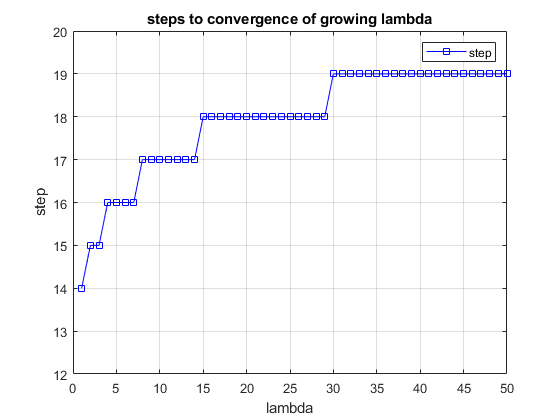

% speed of convergence
clear;
%generate m
m = 10*rand(100,1);
x = sort(m);
y = zeros(100,1);
for i = 1:100
    %generate pertubation
    epsilon = 0.01*randn;
    y(i)=f(x(i))+epsilon;
end
step = zeros(1,50);
est_c = [1,1,1,1]';
for i = 1:50
    lambda = i;
    [test,k] = LevenMar(est_c,x,y,lambda);
    step(i) = k;
end

interval = linspace(1,50,50);

figure(1)
plot(interval,step,'bs-');grid;
ylim([12 20]);
xlabel('lambda');ylabel('step');
title('steps to convergence of growing lambda');
legend('step');

function y = func(x)
    y = 816*x^3-3835*x^2+6000*x-3125;
end
% implement newton's method, 
% func is the original poly
% dfunc is the derivative of this poly
% d2func is the second order derivative
function y=dfunc(x)
    y = 3*816*x^2-3835*2*x+6000;
end

function y=d2func(x)
    y = 6*816*x-2*3835;
end

function y = Newton(x)
    y = x-func(x)/dfunc(x);
end

function b = basin(x)
    b = abs(2*dfunc(x)/d2func(x));
end

% functions of problem 2

function y=f(x)
y=exp(-x/2)*sin(2*x);
end

function y=fc(x,c_1,c_2,c_3,c_4)
    y = c_1*exp(-c_2*x)*sin(c_3*x+c_4);
end

function y=fc_1(x,c_1,c_2,c_3,c_4)
    y = exp(-c_2*x)*sin(c_3*x+c_4);
end

function y=fc_2(x,c_1,c_2,c_3,c_4)
    y = -x*c_1*exp(-c_2*x)*sin(c_3*x+c_4);
end

function y=fc_3(x,c_1,c_2,c_3,c_4)
    y = x*c_1*exp(-c_2*x)*cos(c_3*x+c_4);
end

function y=fc_4(x,c_1,c_2,c_3,c_4)
    y = c_1*exp(-c_2*x)*cos(c_3*x+c_4);
end

function c_delta=Newton_Gauss(y_c,y,J)
    c_delta = (J'*J)\(J'*(y-y_c));
end

function c_delta=robust_Newton_Gauss(y_c,y,J,lambda)
    c_delta = (J'*J+lambda*diag(diag(J'*J)))\(J'*(y-y_c));
end

% the function 
% k is the count for steps
function [est_c,k] = jacobian(est_c,x,y)
    c_delta=ones(4,1);
    k = 1;
    while norm(c_delta,2)>1e-10
        c_1=est_c(1);
        c_2=est_c(2);
        c_3=est_c(3);
        c_4=est_c(4);
        J=zeros(100,4);
        y_c=zeros(100,1);
        for i=1:100
            J(i,1)=fc_1(x(i),c_1,c_2,c_3,c_4);
            J(i,2)=fc_2(x(i),c_1,c_2,c_3,c_4);
            J(i,3)=fc_3(x(i),c_1,c_2,c_3,c_4);
            J(i,4)=fc_4(x(i),c_1,c_2,c_3,c_4);
            y_c(i)=fc(x(i),c_1,c_2,c_3,c_4);
        end

        c_delta = Newton_Gauss(y_c,y,J);
        est_c = est_c + c_delta;
        k = k+1;
    end
end
%this is used for test quadratic or linear
function [lin,qua, est_c] = testConv(est_c,x,y,true_c)
    lin = zeros(1,20);
    qua = zeros(1,20);
    c_delta=ones(4,1);
    k = 1;
    while norm(c_delta,2)>1e-10
        c_1=est_c(1);
        c_2=est_c(2);
        c_3=est_c(3);
        c_4=est_c(4);
        J=zeros(100,4);
        y_c=zeros(100,1);
        for i=1:100
            J(i,1)=fc_1(x(i),c_1,c_2,c_3,c_4);
            J(i,2)=fc_2(x(i),c_1,c_2,c_3,c_4);
            J(i,3)=fc_3(x(i),c_1,c_2,c_3,c_4);
            J(i,4)=fc_4(x(i),c_1,c_2,c_3,c_4);
            y_c(i)=fc(x(i),c_1,c_2,c_3,c_4);
        end
       
        c_delta = Newton_Gauss(y_c,y,J);
        e_k = norm(est_c-true_c,2);
        est_c = est_c + c_delta;
        e_k1=norm(est_c-true_c,2);
        lin(k) = e_k1/e_k;
        qua(k) = e_k1/e_k^2;
        k = k+1;
    end
end
% function for Leveenberg-Marquadt Alg
function [est_c,k] = LevenMar(est_c,x,y,lambda)
    c_delta=ones(4,1);
    k = 1;
    while norm(c_delta,2)>1e-10
        c_1=est_c(1);
        c_2=est_c(2);
        c_3=est_c(3);
        c_4=est_c(4);
        J=zeros(100,4);
        y_c=zeros(100,1);
        for i=1:100
            J(i,1)=fc_1(x(i),c_1,c_2,c_3,c_4);
            J(i,2)=fc_2(x(i),c_1,c_2,c_3,c_4);
            J(i,3)=fc_3(x(i),c_1,c_2,c_3,c_4);
            J(i,4)=fc_4(x(i),c_1,c_2,c_3,c_4);
            y_c(i)=fc(x(i),c_1,c_2,c_3,c_4);
        end

        c_delta = robust_Newton_Gauss(y_c,y,J,lambda);
        est_c = est_c + c_delta;
        k = k+1;
        lambda = lambda/2;
    end
end

function C = comb(pic1,pic2,outputname)% this is the function to combine two figures
A = imread(pic1);
B = imread(pic2);
C = [A,B];
imwrite(C,outputname);
end